#### 1-Definir o conjunto de dados

clear; clc;
interval = (-10:0.05:10);

#### 2-Definir as funções de pertinencia

Define a função de entrada

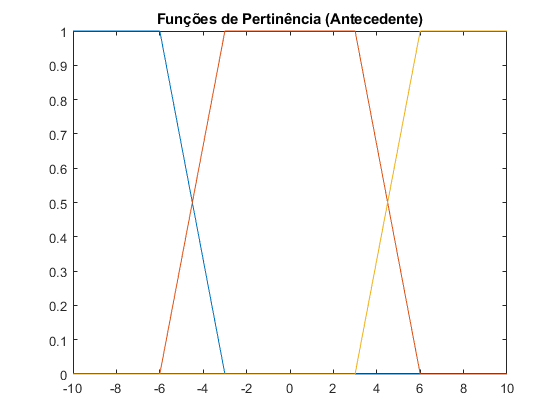

antecedente = {@(x)trapezoidal(x,-20,-15,-6,-3), ... 
    @(x)trapezoidal(x,-6,-3,3,6), @(x)trapezoidal(x,3,6,15,20)};

figure(1);
for item = antecedente
    fplot(item, [-10,10]); hold on;
end
hold off;  title("Funções de Pertinência (Antecedente)");

Define as funções de saída

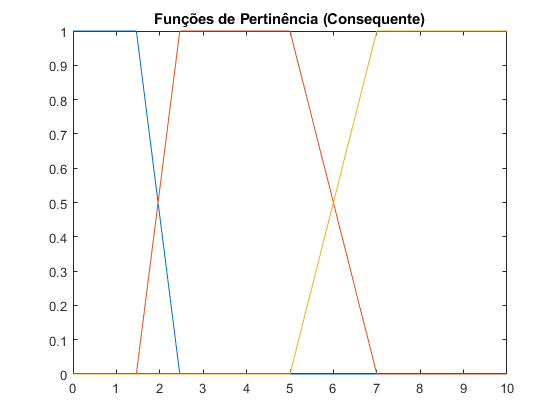

consequente = {@(x)trapezoidal(x,-2.46,-1.46,1.46,2.46), ... 
    @(x)trapezoidal(x,1.46,2.46,5,7), @(x)trapezoidal(x,5,7,13,15)};
intervalAntecedente = (0:0.1:10);

figure(2);
for item = consequente
    fplot(item, [0,10]); hold on;
end
hold off;  title("Funções de Pertinência (Consequente)");

#### 3-Calcular o grau de ativação dos antecedentes (W) (Grau de ativação das funções de pertinencia)

As regras são:

- Se x1 é a1 -> y é c3

- Se x2 é a2 -> y é c2

- Se x3 é a3 -> y é c1

#### 4-Calcular a saida de cada regra (minimo) (antecedente -> consequente)

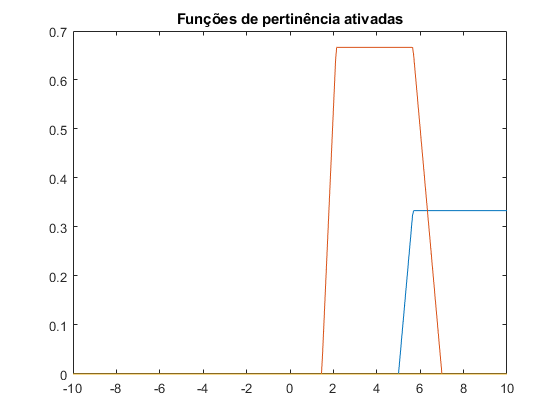

testValue = -4;
w1 = minIntersection(interval,consequente{3},antecedente{1}(testValue));
w2 = minIntersection(interval,consequente{2},antecedente{2}(testValue));
w3 = minIntersection(interval,consequente{1},antecedente{3}(testValue));
plot(interval, w1, interval, w2, interval, w3); 
title("Funções de pertinência ativadas");

#### 5-Agregar as saidas das regras (maximo)

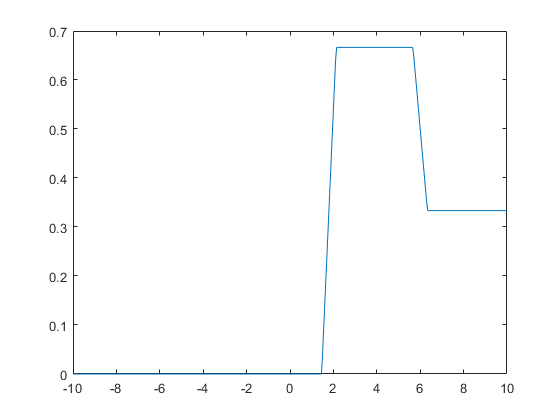

res = maxUnion(w1,w2,w3);
plot(interval, res);

#### 6-Defuzificar - saida com valor númerico

z = res;
output = defuzz(z, res, 'centroid');
disp(output);

    0.5439



#### Testando com N valores

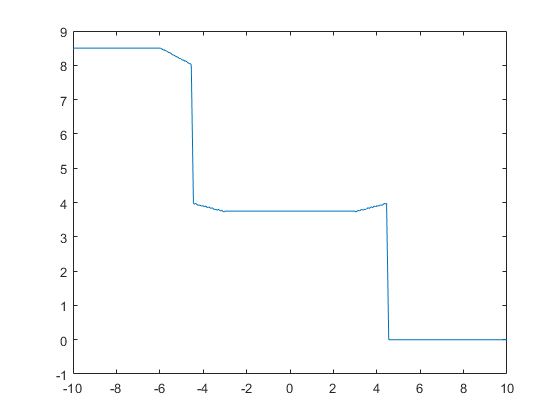

cont = 1;   output = N;
for testValue = interval
    w1 = minIntersection(interval, consequente{3}, antecedente{1}(testValue));
    w2 = minIntersection(interval, consequente{2}, antecedente{2}(testValue));
    w3 = minIntersection(interval, consequente{1}, antecedente{3}(testValue));
    
    res = maxUnion(w1,w2,w3);
    output(cont) = defuzz(interval, res, 'mom');      
    cont = cont + 1;
end
figure(6); 
plot(N,output); 

#### Define a função de pertinência do antecedente

function res = trapezoidal(x,a,m,n,b)
    a = min((x-a)./(m-a), (b-x)./(b-n));
    res = max(min(a, 1), 0);
end

#### Funções de União (S - normas)

Zadeh - max

function res = maxUnion(func1, func2, func3)
    res = func1;
    for i = 1:1:length(func1)
        res(i) = max([func1(i), func2(i), func3(i)]);
    end
end

#### Funçoes de Intercessão ( T - normas )

Zadeh - min

function res = minIntersection(x, func, maxVal)
    res = min(func(x), maxVal);
end